# Setup

clc
clear
warning('off')

%Get Current directory
mlxpath = DirectoryHandler;

%Input signals

%Position Input
N_temp = 534; %TODO: Increase time to match Land (issues with stitching chirp)
delta_t = 0.01;
t = 0:delta_t:2*N_temp*delta_t;
NT = 2*N_temp;
t1 = 0:delta_t:N_temp*delta_t;
I_p(1:N_temp+1) = 1-chirp(t1,0.5,N_temp*delta_t,1);
I_p(N_temp+1:2*N_temp+1) = 1-chirp(t1,1,N_temp*delta_t,3);

%Velocity Input
I_v = diff(I_p)/delta_t;

%Time Alignment
I_p = I_p(1:NT);
t = t(1:NT);

%Concatenate Time Series
P_in = [t;I_p]';
V_in = [t;I_v]';

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'CombinedModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

# Figure A: Low Gain Smooth with only Position feedback

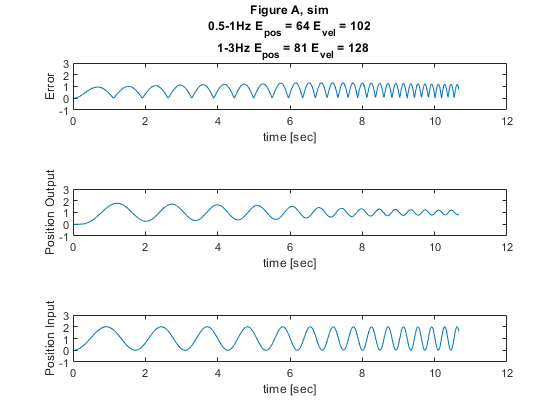

%Set simulation parameters for scenario A

%Gains
PSM = 3;
VSM = 0;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate
out = sim('combinedModel.slx');

%Outputs
a_pout = out.P_out;
a_vout = out.V_out;

%Position Error
a_error = abs(a_pout-P_in(:,2));

%Difference Equation Approach
[a_diff_pout, a_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
a_diff_error = abs(a_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\a_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,a_diff_error,'-k',t,a_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,a_diff_pout,'-k',t,a_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-a_pout');
E_v = abs(I_v-a_vout');

%Cumulative normalized Tracking Error: sim
asim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
asim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
asim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
asim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: diff
E_p = abs(I_p-a_diff_pout);
E_v = abs(I_v-a_diff_vout);

%Cumulative normalized Tracking Error: diff
adiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
adiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
adiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
adiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,a_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure A, sim';
    ['0.5-1Hz E_{pos} = ',num2str(asim_El_pos),' E_{vel} = ',num2str(asim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(asim_Eh_pos),' E_{vel} = ',num2str(asim_Eh_vel)]} )
subplot(3,1,2)
plot(t,a_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

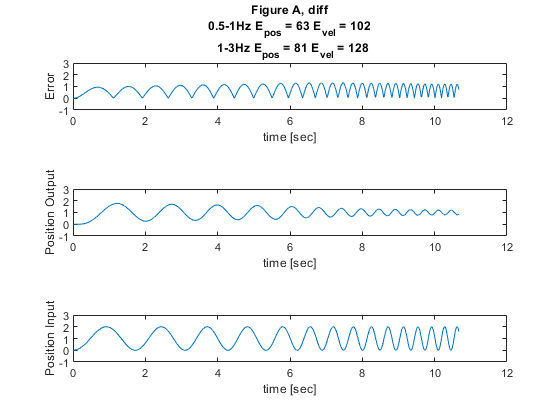


%Diff Figure
figure
subplot(3,1,1)
plot(t,a_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure A, diff';
    ['0.5-1Hz E_{pos} = ',num2str(adiff_El_pos),' E_{vel} = ',num2str(adiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(adiff_Eh_pos),' E_{vel} = ',num2str(adiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,a_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure B: Low Gain Smooth with only Velocity feedback

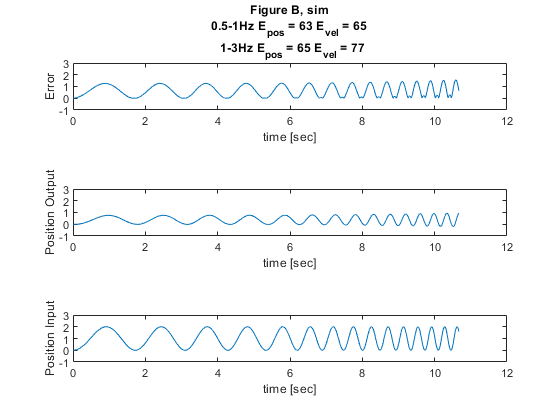

%Set simulation parameters for scenario B

%Gains
PSM = 0;
VSM = 0.6;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
b_pout = out.P_out;
b_vout = out.V_out;

%Position Error
b_error = abs(b_pout-P_in(:,2));

%Difference Equation Approach
[b_diff_pout, b_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
b_diff_error = abs(b_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\b_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,b_diff_error,'-k',t,b_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,b_diff_pout,'-k',t,b_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-b_pout');
E_v = abs(I_v-b_vout');

%Cumulative normalized Tracking Error: sim
bsim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
bsim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
bsim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
bsim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: diff
E_p = abs(I_p-b_diff_pout);
E_v = abs(I_v-b_diff_vout);

%Cumulative normalized Tracking Error: diff
bdiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
bdiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
bdiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
bdiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,b_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure B, sim';
    ['0.5-1Hz E_{pos} = ',num2str(bsim_El_pos),' E_{vel} = ',num2str(bsim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(bsim_Eh_pos),' E_{vel} = ',num2str(bsim_Eh_vel)]} )
subplot(3,1,2)
plot(t,b_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

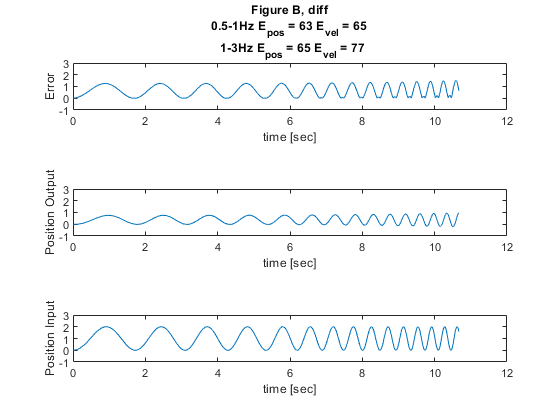


%Diff Figure
figure
subplot(3,1,1)
plot(t,b_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure B, diff';
    ['0.5-1Hz E_{pos} = ',num2str(bdiff_El_pos),' E_{vel} = ',num2str(bdiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(bdiff_Eh_pos),' E_{vel} = ',num2str(bdiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,b_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure C: High Gain Smooth with only Position feedback

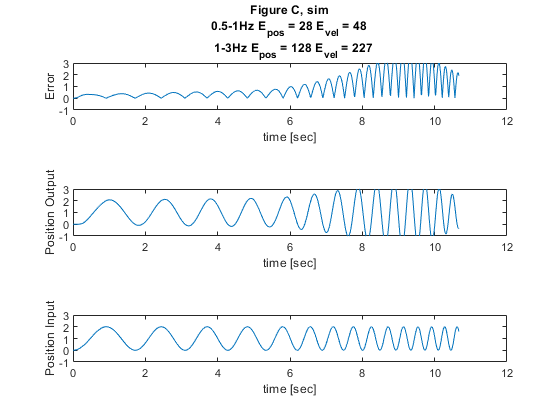

%Set simulation parameters for scenario C

%Gains
PSM = 11;
VSM = 0;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
c_pout = out.P_out;
c_vout = out.V_out;

%Position Error
c_error = abs(c_pout-P_in(:,2));

%Difference Equation Approach
[c_diff_pout, c_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
c_diff_error = abs(c_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\c_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,c_diff_error,'-k',t,c_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,c_diff_pout,'-k',t,c_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-c_pout');
E_v = abs(I_v-c_vout');

%Cumulative normalized Tracking Error: sim
csim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
csim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
csim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
csim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-c_diff_pout);
E_v = abs(I_v-c_diff_vout);

%Cumulative normalized Tracking Error: sim
cdiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
cdiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
cdiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
cdiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,c_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure C, sim';
    ['0.5-1Hz E_{pos} = ',num2str(csim_El_pos),' E_{vel} = ',num2str(csim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(csim_Eh_pos),' E_{vel} = ',num2str(csim_Eh_vel)]} )
subplot(3,1,2)
plot(t,c_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

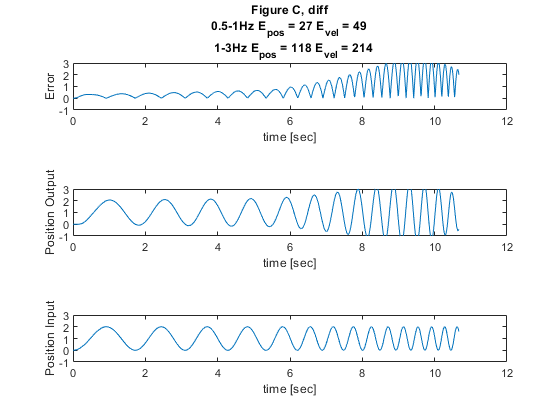


%Diff Figure
figure
subplot(3,1,1)
plot(t,c_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure C, diff';
    ['0.5-1Hz E_{pos} = ',num2str(cdiff_El_pos),' E_{vel} = ',num2str(cdiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(cdiff_Eh_pos),' E_{vel} = ',num2str(cdiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,c_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure D: Smooth with both position and velocity feedback

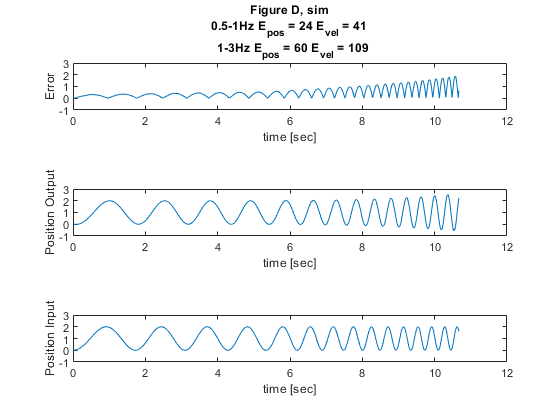

%Set simulation parameters for scenario D

%Gains
PSM = 11;
VSM = 0.6;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
d_pout = out.P_out;
d_vout = out.V_out;

%Position Error
d_error = abs(d_pout-P_in(:,2));

%Difference Equation Approach
[d_diff_pout, d_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
d_diff_error = abs(d_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\d_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,d_diff_error,'-k',t,d_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,d_diff_pout,'-k',t,d_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-d_pout');
E_v = abs(I_v-d_vout');

%Cumulative normalized Tracking Error: sim
dsim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
dsim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
dsim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
dsim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-d_diff_pout);
E_v = abs(I_v-d_diff_vout);

%Cumulative normalized Tracking Error: sim
ddiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
ddiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
ddiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
ddiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,d_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure D, sim';
    ['0.5-1Hz E_{pos} = ',num2str(dsim_El_pos),' E_{vel} = ',num2str(dsim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(dsim_Eh_pos),' E_{vel} = ',num2str(dsim_Eh_vel)]} )
subplot(3,1,2)
plot(t,d_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

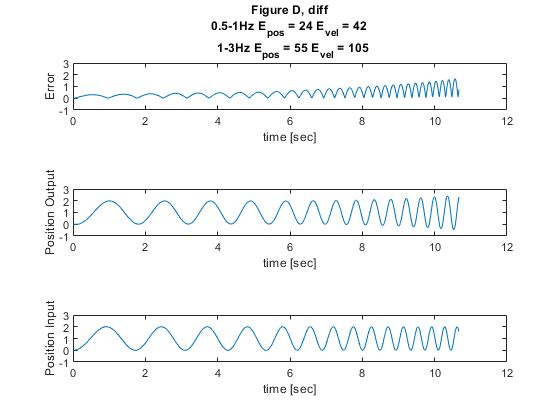


%Diff Figure
figure
subplot(3,1,1)
plot(t,d_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure D, diff';
    ['0.5-1Hz E_{pos} = ',num2str(ddiff_El_pos),' E_{vel} = ',num2str(ddiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(ddiff_Eh_pos),' E_{vel} = ',num2str(ddiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,d_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure E: Saccadic with position only

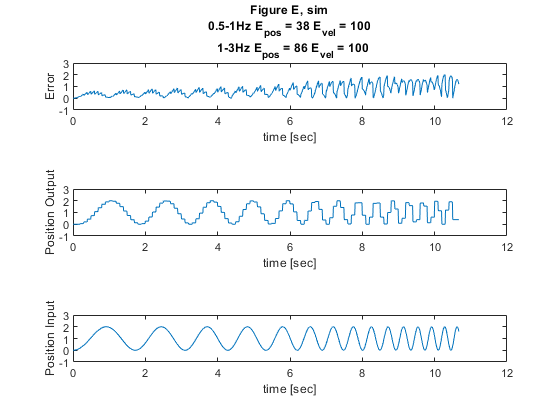

%Set simulation parameters for scenario E

%Gains
PSM = 0;
VSM = 0;
VSA = 0;
PSA = 1;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
e_pout = out.P_out;
e_vout = out.V_out;

%Position Error
e_error = abs(e_pout-P_in(:,2));

%Difference Equation Approach
[e_diff_pout, e_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
e_diff_error = abs(e_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\e_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,e_diff_error,'-k',t,e_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,e_diff_pout,'-k',t,e_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-e_pout');
E_v = abs(I_v-e_vout');

%Cumulative normalized Tracking Error: sim
esim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
esim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
esim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
esim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-e_diff_pout);
E_v = abs(I_v-e_diff_vout);

%Cumulative normalized Tracking Error: sim
ediff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
ediff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
ediff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
ediff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,e_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure E, sim';
    ['0.5-1Hz E_{pos} = ',num2str(esim_El_pos),' E_{vel} = ',num2str(esim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(esim_Eh_pos),' E_{vel} = ',num2str(esim_Eh_vel)]} )
subplot(3,1,2)
plot(t,e_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

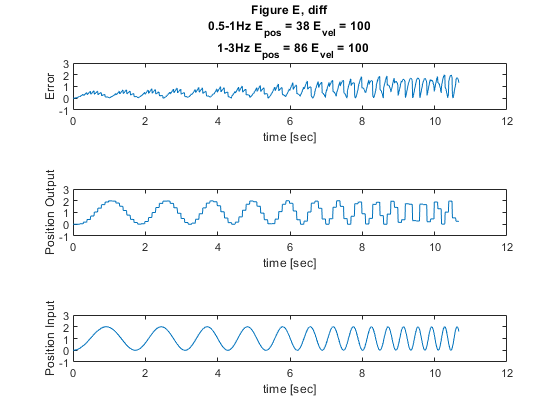


%Diff Figure
figure
subplot(3,1,1)
plot(t,e_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure E, diff';
    ['0.5-1Hz E_{pos} = ',num2str(ediff_El_pos),' E_{vel} = ',num2str(ediff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(ediff_Eh_pos),' E_{vel} = ',num2str(ediff_Eh_vel)]} )
subplot(3,1,2)
plot(t,e_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure F: Saccadic with position and velocity

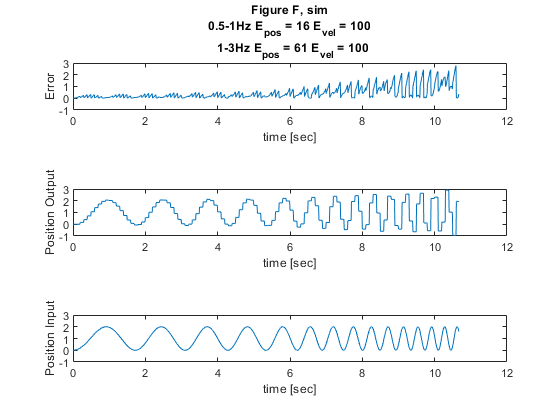

%Set simulation parameters for scenario F

%Gains
PSM = 0;
VSM = 0;
VSA = 0.1;
PSA = 1;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
f_pout = out.P_out;
f_vout = out.V_out;

%Position Error
f_error = abs(f_pout-P_in(:,2));

%Difference Equation Approach
[f_diff_pout, f_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
f_diff_error = abs(f_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\f_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,f_diff_error,'-k',t,f_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,f_diff_pout,'-k',t,f_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-f_pout');
E_v = abs(I_v-f_vout');

%Cumulative normalized Tracking Error: sim
fsim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
fsim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
fsim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
fsim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-f_diff_pout);
E_v = abs(I_v-f_diff_vout);

%Cumulative normalized Tracking Error: sim
fdiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
fdiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
fdiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
fdiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,f_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure F, sim';
    ['0.5-1Hz E_{pos} = ',num2str(fsim_El_pos),' E_{vel} = ',num2str(fsim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(fsim_Eh_pos),' E_{vel} = ',num2str(fsim_Eh_vel)]} )
subplot(3,1,2)
plot(t,f_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

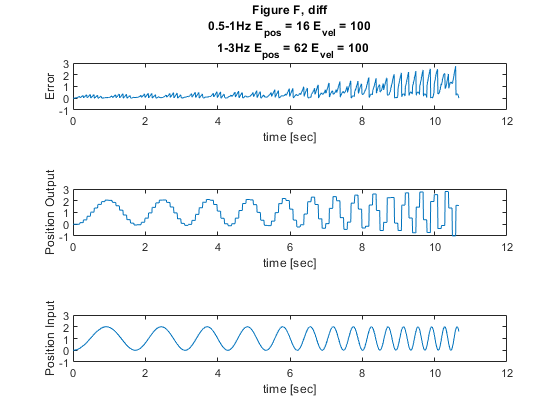


%Diff Figure
figure
subplot(3,1,1)
plot(t,f_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure F, diff';
    ['0.5-1Hz E_{pos} = ',num2str(fdiff_El_pos),' E_{vel} = ',num2str(fdiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(fdiff_Eh_pos),' E_{vel} = ',num2str(fdiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,f_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure G: Saccadic with position and velocity + smooth velocity feedback

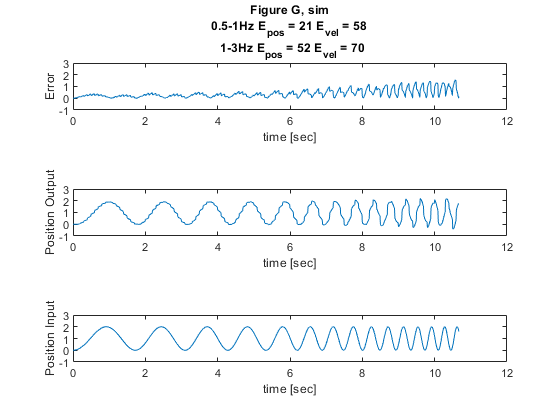

%Set simulation parameters for scenario G

%Gains
PSM = 0;
VSM = 0.8;
VSA = 0.05; %TODO: Why does Land use 5? In this sim, that kills the continuous leg
PSA = 1;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 2;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
g_pout = out.P_out;
g_vout = out.V_out;

%Position Error
g_error = abs(g_pout-P_in(:,2));

%Difference Equation Approach
[g_diff_pout, g_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
g_diff_error = abs(g_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\g_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,g_diff_error,'-k',t,g_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,g_diff_pout,'-k',t,g_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-g_pout');
E_v = abs(I_v-g_vout');

%Cumulative normalized Tracking Error: sim
gsim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
gsim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
gsim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
gsim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-g_diff_pout);
E_v = abs(I_v-g_diff_vout);

%Cumulative normalized Tracking Error: sim
gdiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
gdiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
gdiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
gdiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,g_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure G, sim';
    ['0.5-1Hz E_{pos} = ',num2str(gsim_El_pos),' E_{vel} = ',num2str(gsim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(gsim_Eh_pos),' E_{vel} = ',num2str(gsim_Eh_vel)]} )
subplot(3,1,2)
plot(t,g_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

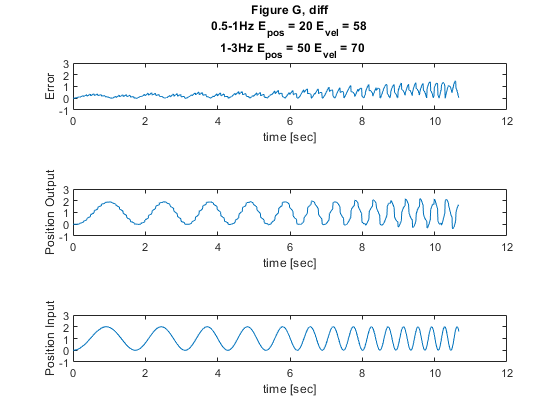


%Diff Figure
figure
subplot(3,1,1)
plot(t,g_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure G, diff';
    ['0.5-1Hz E_{pos} = ',num2str(gdiff_El_pos),' E_{vel} = ',num2str(gdiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(gdiff_Eh_pos),' E_{vel} = ',num2str(gdiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,g_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Figure H: Saccadic with position and velocity + smooth velocity feedback w/ thresholding

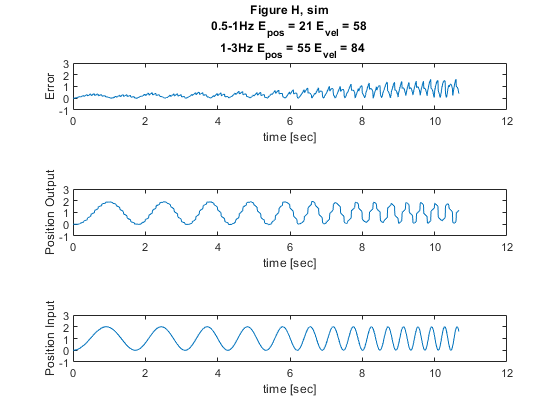

%Set simulation parameters for scenario G

%Gains
PSM = 0;
VSM = 0.8;
VSA = .05; %TODO: Why does Land use 5? In this sim, that kills the continuous leg
PSA = 1;

%Delay and zero-order hold time
delay = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf; 
VSM_sat_low = -inf;
vout_up = 3;
vout_low = -3;

%Mystery Divisor
divisor = 2;

%Simulate

out = sim('combinedModel.slx');

%Outputs
h_pout = out.P_out;
h_vout = out.V_out;

%Position Error
h_error = abs(h_pout-P_in(:,2));

%Difference Equation Approach
[h_diff_pout, h_diff_vout] = combinedDiffEquation(PSM,VSM,PSA,VSA,delay,...
    PSM_sat_up,PSM_sat_low,VSM_sat_up,VSM_sat_low,PSA_sat_up,...
    PSA_sat_low,VSA_sat_up,VSA_sat_low,vout_up,vout_low,NT,I_p,I_v,delta_t,divisor);

%Diff Position Error
h_diff_error = abs(h_diff_pout' - P_in(:,2));

% %Comparison to previous data for sanity check
% load(mlxpath + '\Previous Work Data for Comparison\h_diff_data.mat')
% figure
% subplot(3,1,1)
% plot(t,h_diff_error,'-k',t,h_E_p,'--r')
% ylim([-1 3])
% subplot(3,1,2)
% plot(t,h_diff_pout,'-k',t,h_O_p,'--r')
% ylim([-1 3])
% subplot(3,1,3)
% plot(P_in(:,1),P_in(:,2))
% ylim([-1 3])

%Error calcs

%Instantaneous Tracking error: sim
E_p = abs(I_p-h_pout');
E_v = abs(I_v-h_vout');

%Cumulative normalized Tracking Error: sim
hsim_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
hsim_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
hsim_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
hsim_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Instantaneous Tracking error: sim
E_p = abs(I_p-h_diff_pout);
E_v = abs(I_v-h_diff_vout);

%Cumulative normalized Tracking Error: sim
hdiff_El_pos = int16(100*cumsum(E_p(1:N_temp))/cumsum(I_p(1:N_temp)));
hdiff_Eh_pos = int16(100*cumsum(E_p(N_temp+1:2*N_temp))/cumsum(I_p(N_temp+1:2*N_temp)));
hdiff_El_vel = int16(100*cumsum(E_v(1:N_temp))/cumsum(abs(I_v(1:N_temp))));
hdiff_Eh_vel = int16(100*cumsum(E_v(N_temp+1:2*N_temp))/cumsum(abs(I_v(N_temp+1:2*N_temp))));

%Sim Figure
figure
subplot(3,1,1)
plot(t,h_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure H, sim';
    ['0.5-1Hz E_{pos} = ',num2str(hsim_El_pos),' E_{vel} = ',num2str(hsim_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(hsim_Eh_pos),' E_{vel} = ',num2str(hsim_Eh_vel)]} )
subplot(3,1,2)
plot(t,h_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

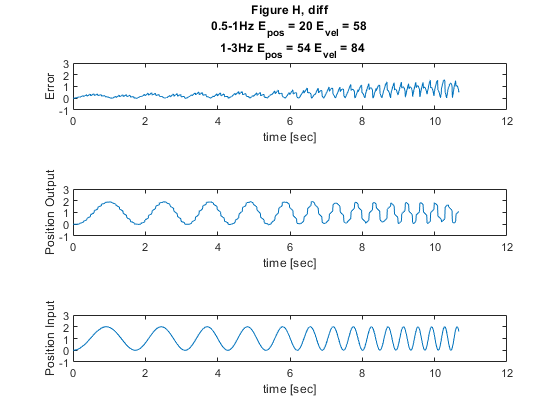


%Diff Figure
figure
subplot(3,1,1)
plot(t,h_diff_error)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Error')
title({'Figure H, diff';
    ['0.5-1Hz E_{pos} = ',num2str(hdiff_El_pos),' E_{vel} = ',num2str(hdiff_El_vel)];
    ['  1-3Hz E_{pos} = ',num2str(hdiff_Eh_pos),' E_{vel} = ',num2str(hdiff_Eh_vel)]} )
subplot(3,1,2)
plot(t,h_diff_pout)
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Output')
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))
ylim([-1 3])
xlabel('time [sec]')
ylabel('Position Input')

# Error Calculations

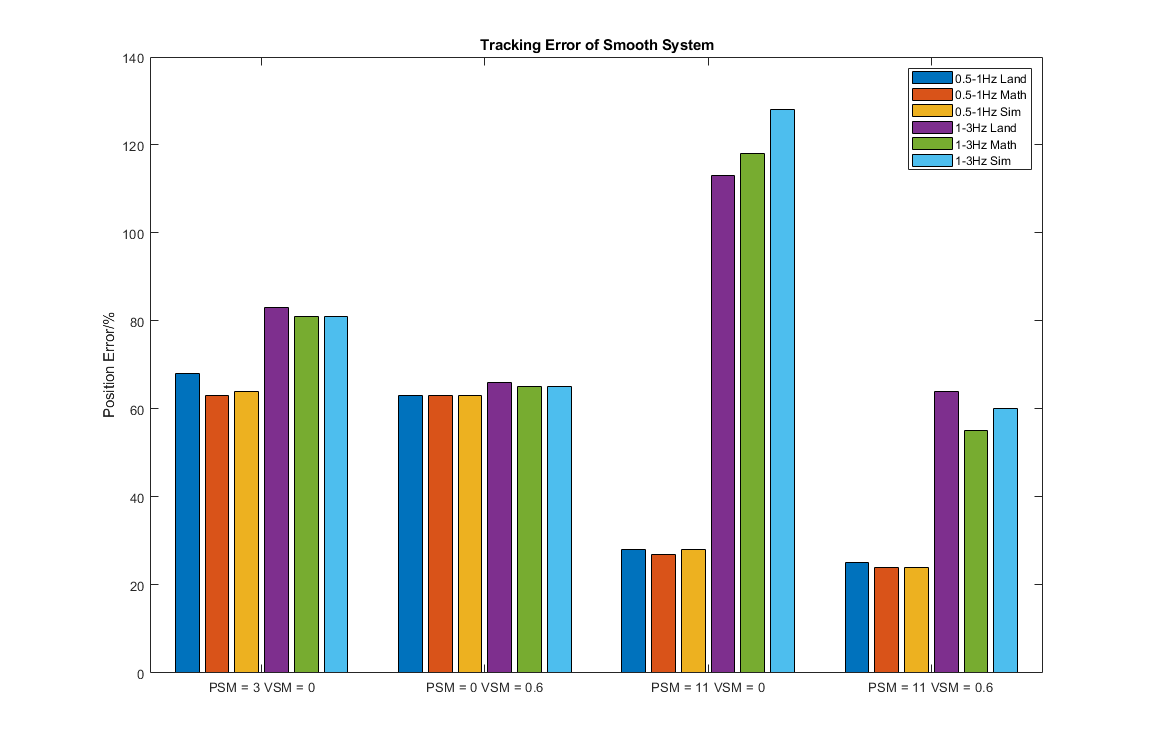

%Position Error from Land
El_pos_land = [68 63 28 25 35 14 15 15]';
Eh_pos_land = [83 66 113 64 89 66 51 51]';
El_pos_diff = [adiff_El_pos bdiff_El_pos cdiff_El_pos ddiff_El_pos ediff_El_pos fdiff_El_pos gdiff_El_pos hdiff_El_pos]';
Eh_pos_diff = [adiff_Eh_pos bdiff_Eh_pos cdiff_Eh_pos ddiff_Eh_pos ediff_Eh_pos fdiff_Eh_pos gdiff_Eh_pos hdiff_Eh_pos]';
El_pos_sim = [asim_El_pos bsim_El_pos csim_El_pos dsim_El_pos esim_El_pos fsim_El_pos gsim_El_pos hsim_El_pos]';
Eh_pos_sim = [asim_Eh_pos bsim_Eh_pos csim_Eh_pos dsim_Eh_pos esim_Eh_pos fsim_Eh_pos gsim_Eh_pos hsim_Eh_pos]';

%Velocity Error from Land
El_vel_land = [106 65 58 47 58 58]';
Eh_vel_land = [124 76 186 107 69 69]';
El_vel_diff = [adiff_El_vel bdiff_El_vel cdiff_El_vel ddiff_El_vel gdiff_El_vel hdiff_El_vel]';
Eh_vel_diff = [adiff_Eh_vel bdiff_Eh_vel cdiff_Eh_vel ddiff_Eh_vel gdiff_Eh_vel hdiff_Eh_vel]';
El_vel_sim = [asim_El_vel bsim_El_vel csim_El_vel dsim_El_vel gsim_El_vel hsim_El_vel]';
Eh_vel_sim = [asim_Eh_vel bsim_Eh_vel csim_Eh_vel dsim_Eh_vel gsim_Eh_vel hsim_Eh_vel]';

% Smooth System
x1 = categorical({'PSM = 3 VSM = 0','PSM = 0 VSM = 0.6','PSM = 11 VSM = 0','PSM = 11 VSM = 0.6'});
x1 = reordercats(x1,{'PSM = 3 VSM = 0','PSM = 0 VSM = 0.6','PSM = 11 VSM = 0','PSM = 11 VSM = 0.6'});
p1 = [El_pos_land(1:4) El_pos_diff(1:4) El_pos_sim(1:4) Eh_pos_land(1:4) Eh_pos_diff(1:4) Eh_pos_sim(1:4)];
v1 = [El_vel_land(1:4) El_vel_diff(1:4) El_vel_sim(1:4) Eh_vel_land(1:4) Eh_vel_diff(1:4) Eh_vel_sim(1:4)];

figure('units','normalized','outerposition',[0 0 0.6 0.7])
bar(x1,p1);
title('Tracking Error of Smooth System')
ylabel('Position Error/%')
legend('0.5-1Hz Land','0.5-1Hz Math','0.5-1Hz Sim','1-3Hz Land','1-3Hz Math','1-3Hz Sim')

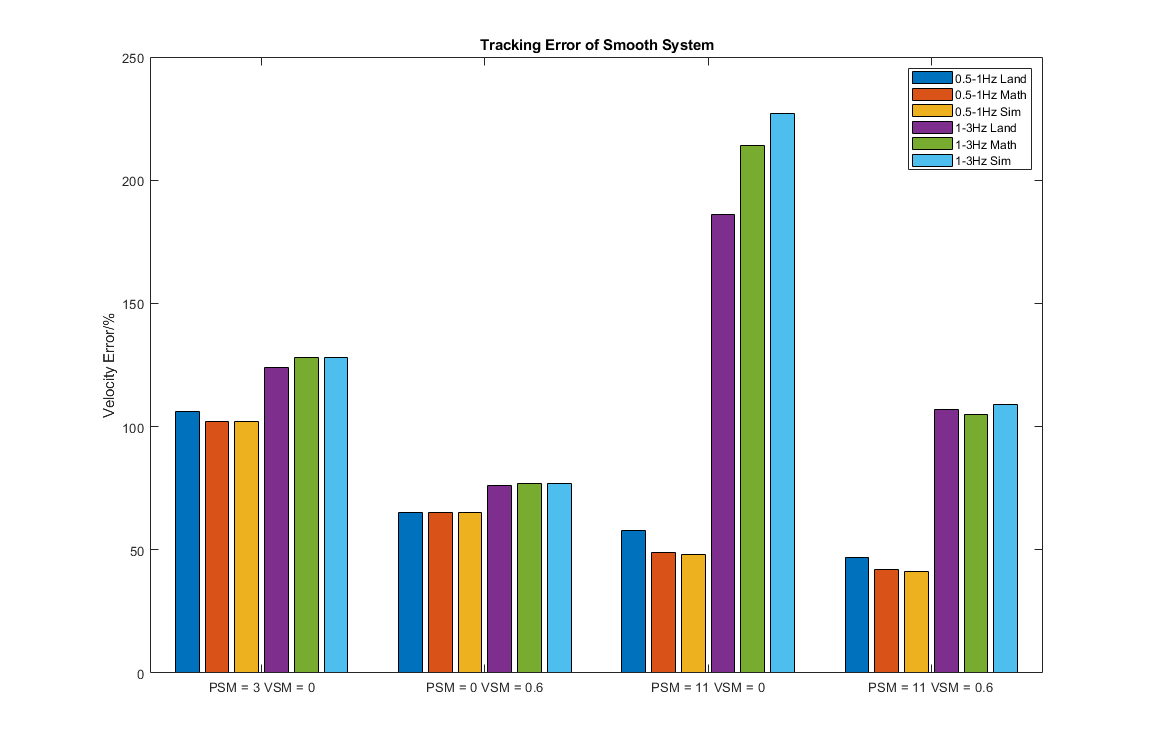


figure('units','normalized','outerposition',[0 0 0.6 0.7])
bar(x1,v1);
title('Tracking Error of Smooth System')
ylabel('Velocity Error/%')
legend('0.5-1Hz Land','0.5-1Hz Math','0.5-1Hz Sim','1-3Hz Land','1-3Hz Math','1-3Hz Sim')

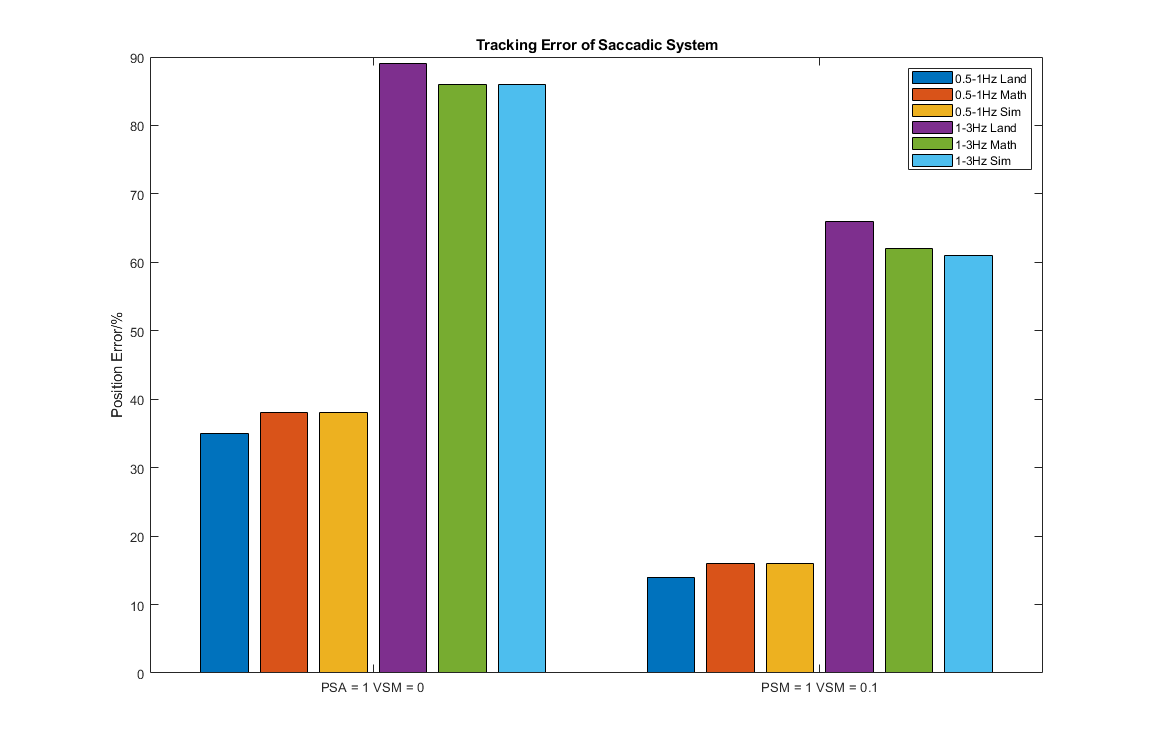


% Saccadic System
x2 = categorical({'PSA = 1 VSM = 0','PSM = 1 VSM = 0.1'});
x2 = reordercats(x2,{'PSA = 1 VSM = 0','PSM = 1 VSM = 0.1'});
p2 = [El_pos_land(5:6) El_pos_diff(5:6) El_pos_sim(5:6) Eh_pos_land(5:6) Eh_pos_diff(5:6) Eh_pos_sim(5:6)];

figure('units','normalized','outerposition',[0 0 0.6 0.7])
bar(x2,p2);
title('Tracking Error of Saccadic System')
ylabel('Position Error/%')
legend('0.5-1Hz Land','0.5-1Hz Math','0.5-1Hz Sim','1-3Hz Land','1-3Hz Math','1-3Hz Sim')

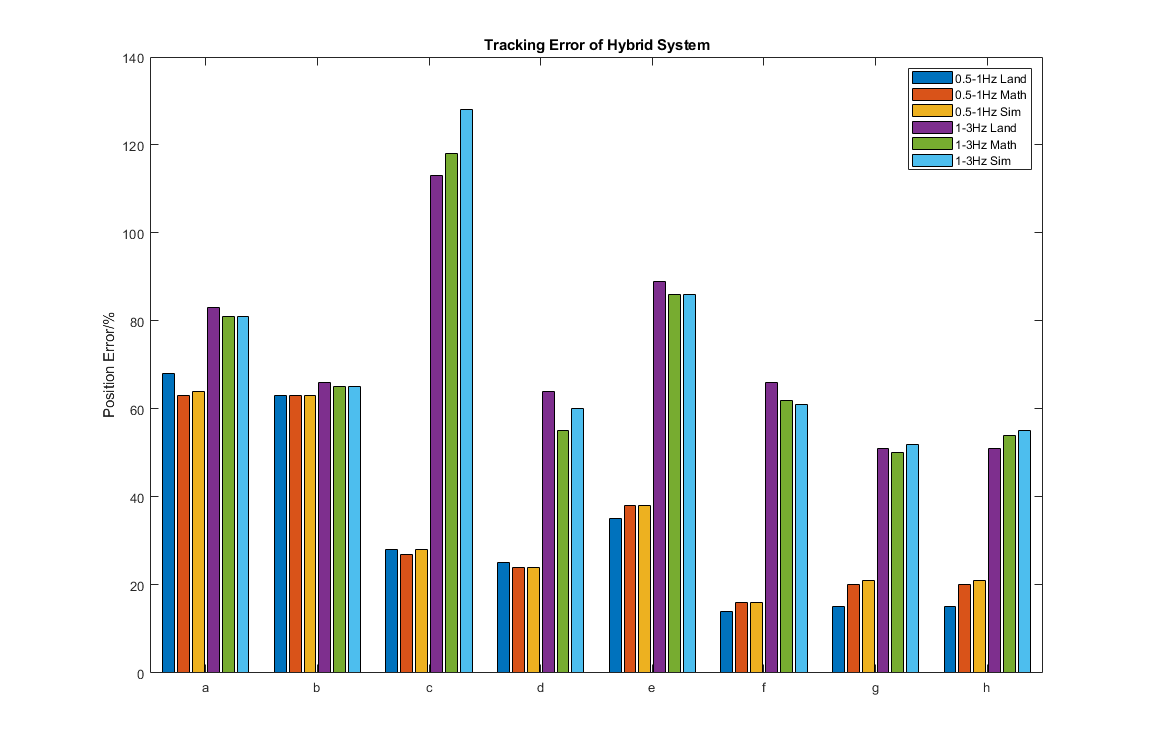


% Total
x3 = categorical({'a','b','c','d','e','f','g','h'});
x3 = reordercats(x3,{'a','b','c','d','e','f','g','h'});
p3 = [El_pos_land El_pos_diff El_pos_sim Eh_pos_land Eh_pos_diff Eh_pos_sim];

figure('units','normalized','outerposition',[0 0 0.6 0.7])
bar(x3,p3);
title('Tracking Error of Hybrid System')
ylabel('Position Error/%')
legend('0.5-1Hz Land','0.5-1Hz Math','0.5-1Hz Sim','1-3Hz Land','1-3Hz Math','1-3Hz Sim')

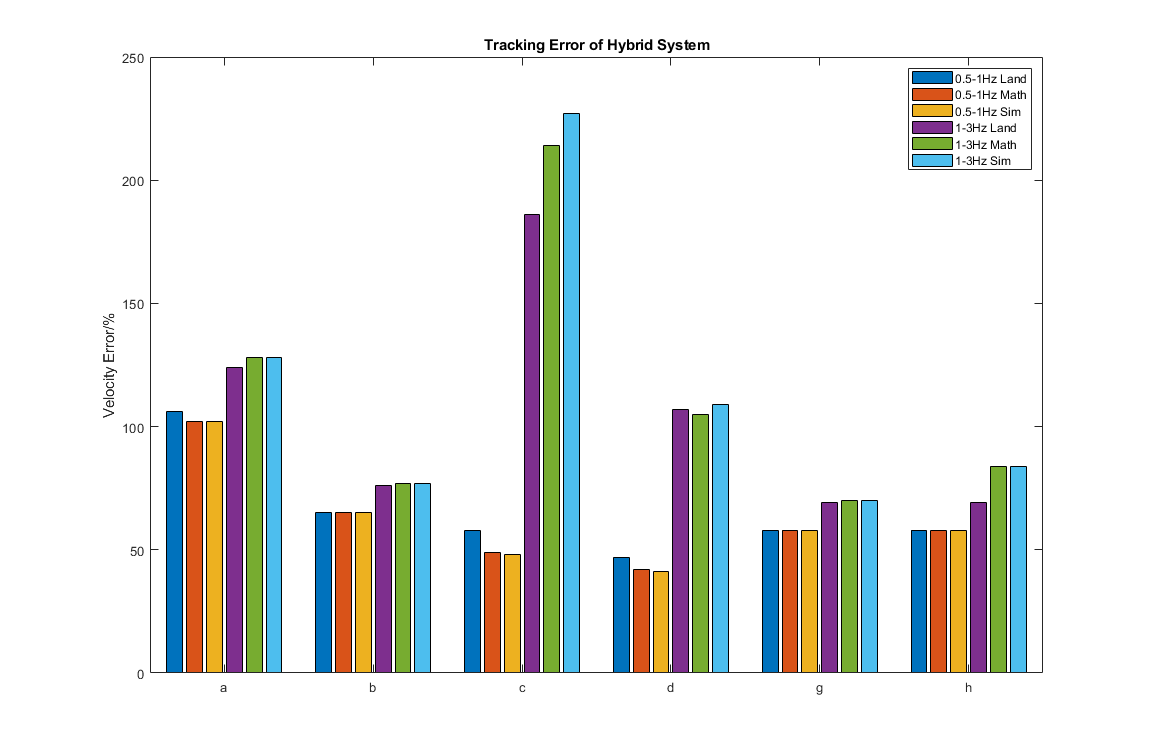


x4 = categorical({'a','b','c','d','g','h'});
x4 = reordercats(x4,{'a','b','c','d','g','h'});
v4 = [El_vel_land El_vel_diff El_vel_sim Eh_vel_land Eh_vel_diff Eh_vel_sim];

figure('units','normalized','outerposition',[0 0 0.6 0.7])
bar(x4,v4);
title('Tracking Error of Hybrid System')
ylabel('Velocity Error/%')
legend('0.5-1Hz Land','0.5-1Hz Math','0.5-1Hz Sim','1-3Hz Land','1-3Hz Math','1-3Hz Sim')